Der nachfolgende Code, soll die Leistung einer Solarzelle für eine horizontale, vertikale oder nachgeführte Ausrichtung an verschiedenen Tagen des Jahres berechnen und vergleichen.

Für die individuelle Nutzung muss der geographische Breitengrad, je nach Standort angepasst werden. Zusätzlich muss die maximale Leistung der Solaranlage durch die Daten der spezifischen Geräts ersetzt werden.  

phi = 48; % Geografische Breitengrad München
specific_days = [80, 172, 266, 355]; % 21. März, 21. Juni, 21. September, 21. Dezember
tage = 1:365; 
P_max = 200; % Maximale Leistung einer ebenen Solaranlage in W/m²

Die Taglänge berechnet die Zeit zwischen dem Sonnenaufgang und dem Sonnenuntergang an einem spezifischen Tag des Jahres und Ort. Der Sonnenaufgang, bzw. -untergang wird als der Zeitpunkt definiert, an dem der Höhenwinkel der Sonne mittels folgender Formel 0 Grad beträgt. Der Zeitpunkt des Sonnenuntergangs wird nur in den ersten 12 Stunden des Tages gesucht, der Untergang nur in den letzten 12 Stunden.

sin𝛼 = sin𝜑 ⋅ sin 𝛿 + cos𝜑 ⋅ cos 𝛿 ⋅ cos H

Die Taglänge wird durch die Differenz zwischen Sonnenaufgang und Sonnenuntergang berechnet.

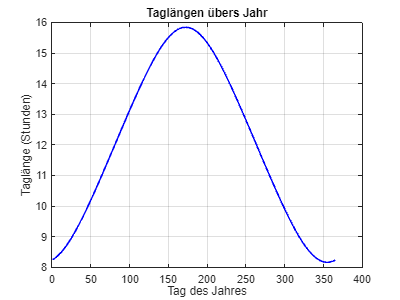

%% Berechnung der Taglängen
taglaengen = zeros(size(tage));

for i = 1:length(tage)
    delta = berechne_deklination(tage(i));
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        taglaengen(i) = sonnenuntergang - sonnenaufgang;
    catch
        taglaengen(i) = 0; % Keine Sonne (z. B. Polarnächte)
    end
end

% Plot der Taglängen übers Jahr
figure;
plot(tage, taglaengen, 'b', 'LineWidth', 1.5);
title('Taglängen übers Jahr');
xlabel('Tag des Jahres');
ylabel('Taglänge (Stunden)');
grid on;


%% Berechnung der Energie für horizontale Solaranlage
E_horizontal_spezifisch = zeros(size(specific_days));
E_horizontal_gesamt = 0;
for doy = 1:365
    delta = berechne_deklination(doy);
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        zeiten = linspace(sonnenaufgang, sonnenuntergang, 20);
        P_t = zeros(size(zeiten));
        for i = 1:length(zeiten)
            alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
            P_t(i) = max(0, P_max * sind(alpha)); % Leistung für horizontale Anlage
        end
        E_tag = trapz(zeiten, P_t); % Energie durch numerische Integration
        E_horizontal_gesamt = E_horizontal_gesamt + E_tag;

        if ismember(doy, specific_days)
            E_horizontal_spezifisch(specific_days == doy) = E_tag;
        end
    catch
        % keine Energie
    end
end

%% Berechnung der Energie für vertikal (Süden ausgerichtet)
E_vertikal_spezifisch = zeros(size(specific_days));
E_vertikal_gesamt = 0;

for doy = 1:365
    delta = berechne_deklination(doy);
    try
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        zeiten = linspace(sonnenaufgang, sonnenuntergang, 20);
        P_t = zeros(size(zeiten));
        for i = 1:length(zeiten)
            alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
            azimut = berechne_azimut(phi, delta, alpha);

            if alpha > 0 && abs(azimut) <= 90
                cos_theta = max(0, sind(alpha) * cosd(azimut));
            else
                cos_theta = 0;
            end

            P_t(i) = max(0, P_max * cos_theta); % Leistung für vertikale Anlage
        end
        E_tag = trapz(zeiten, P_t); % Energie durch numerische Integration
        E_vertikal_gesamt = E_vertikal_gesamt + E_tag;

        if ismember(doy, specific_days)
            E_vertikal_spezifisch(specific_days == doy) = E_tag;
        end
    catch
        % Keine Energie
    end
end

%% Ergebnisse anzeigen
% Spezifische Tage und Energie (horizontal und vertikal)
tage_labels = {'21. März', '21. Juni', '21. September', '21. Dezember'};
energie_tabelle = table(...
    tage_labels', ...
    E_horizontal_spezifisch', ...
    E_vertikal_spezifisch', ...
    'VariableNames', {'Datum', 'Energie_Horizontal (Wh)', 'Energie_Vertikal (Wh)'});

% Tabelle anzeigen
disp('Energie an spezifischen Tagen:');

Energie an spezifischen Tagen:


disp(energie_tabelle);

          Datum          Energie_Horizontal (Wh)    Energie_Vertikal (Wh)
    _________________    _______________________    _____________________

    {'21. März'     }            1007.5                         0        
    {'21. Juni'     }            1755.5                    73.254        
    {'21. September'}            988.72                         0        
    {'21. Dezember' }            338.41                         0        




disp('Gesamte Jahresenergie:');

Gesamte Jahresenergie:


disp(['Horizontale Anlage: ', num2str(E_horizontal_gesamt), ' Wh']);

Horizontale Anlage: 376901.0452 Wh


disp(['Vertikale Anlage: ', num2str(E_vertikal_gesamt), ' Wh']);

Vertikale Anlage: 5517.7179 Wh



% Optimierung der Ausrichtung
beta_range = 0:5:90; % Neigungswinkel von 0° bis 90°
gamma_range = -180:10:180; % Azimutwinkel von -180° bis +180°

% Ergebnisse initialisieren
optimal_spezifisch = struct('beta', [], 'gamma', [], 'energie', []);
E_optimal_gesamt = 0;
beta_optimal_jahr = 0;
gamma_optimal_jahr = 0;

% Berechnung für spezifische Tage
for d = 1:length(specific_days)
    doy = specific_days(d);
    E_best = 0;
    beta_best = 0;
    gamma_best = 0;

    for beta = beta_range
        for gamma = gamma_range
            delta = berechne_deklination(doy);
            [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
            zeiten = linspace(sonnenaufgang, sonnenuntergang, 20);
            P_t = zeros(size(zeiten));

            for i = 1:length(zeiten)
                alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
                azimut_sonne = berechne_azimut(phi, delta, alpha);

                % Berechnung der Vektoren
                vektor_sonne = [cosd(alpha) * sind(azimut_sonne), cosd(alpha) * cosd(azimut_sonne), sind(alpha)];
                vektor_anlage = [sind(beta) * sind(gamma), sind(beta) * cosd(gamma), cosd(beta)];

                % Punktprodukt
                cos_theta = max(0, dot(vektor_sonne, vektor_anlage));
                P_t(i) = max(0, P_max * cos_theta);
            end

            E_tag = trapz(zeiten, P_t);
            if E_tag > E_best
                E_best = E_tag;
                beta_best = beta;
                gamma_best = gamma;
            end
        end
    end

    optimal_spezifisch(d).beta = beta_best;
    optimal_spezifisch(d).gamma = gamma_best;
    optimal_spezifisch(d).energie = E_best;
end

% Berechnung für das gesamte Jahr
for beta = beta_range
    for gamma = gamma_range
        E_total = 0;

        for doy = 1:365
            delta = berechne_deklination(doy);
            [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
            zeiten = linspace(sonnenaufgang, sonnenuntergang, 20);
            P_t = zeros(size(zeiten));

            for i = 1:length(zeiten)
                alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
                azimut_sonne = berechne_azimut(phi, delta, alpha);

                % Berechnung der Vektoren
                vektor_sonne = [cosd(alpha) * sind(azimut_sonne), cosd(alpha) * cosd(azimut_sonne), sind(alpha)];
                vektor_anlage = [sind(beta) * sind(gamma), sind(beta) * cosd(gamma), cosd(beta)];

                % Punktprodukt
                cos_theta = max(0, dot(vektor_sonne, vektor_anlage));
                P_t(i) = max(0, P_max * cos_theta);
            end

            E_total = E_total + trapz(zeiten, P_t);
        end

        if E_total > E_optimal_gesamt
            E_optimal_gesamt = E_total;
            beta_optimal_jahr = beta;
            gamma_optimal_jahr = gamma;
        end
    end
end

verbesserungsfaktor = E_optimal_gesamt / E_horizontal_gesamt;

% Ergebnisse anzeigen
tage_labels = {'21. März', '21. Juni', '21. September', '21. Dezember'};
energie_optimal_tabelle = table(...
    tage_labels', ...
    [optimal_spezifisch(:).beta]', ...
    [optimal_spezifisch(:).gamma]', ...
    [optimal_spezifisch(:).energie]', ...
    'VariableNames', {'Datum', 'Beta (°)', 'Gamma (°)', 'Energie (Wh)'});

disp('Optimale Ausrichtung für spezifische Tage:');

Optimale Ausrichtung für spezifische Tage:


disp(energie_optimal_tabelle);

          Datum          Beta (°)    Gamma (°)    Energie (Wh)
    _________________    ________    _________    ____________

    {'21. März'     }       60          130          2147.4   
    {'21. Juni'     }       50           90          2719.6   
    {'21. September'}       60          130          2135.2   
    {'21. Dezember' }       80          150          1565.5   




fprintf('\nOptimale Ausrichtung für das gesamte Jahr:\n');


Optimale Ausrichtung für das gesamte Jahr:


fprintf('Beta = %.1f°, Gamma = %.1f°, Energie = %.2f Wh\n', beta_optimal_jahr, gamma_optimal_jahr, E_optimal_gesamt);

Beta = 60.0°, Gamma = 120.0°, Energie = 735576.51 Wh



fprintf('\nVerbesserungsfaktor im Vergleich zur horizontalen Anlage: %.2f\n', verbesserungsfaktor);


Verbesserungsfaktor im Vergleich zur horizontalen Anlage: 1.95


Folgender Code-Abschnitt beinhaltet die Nachführung der Anlage zur Sonne hin und die Energiegewinnung. Zudem wird die gewonnene Energie mit derjenigen Verglichen, sollte die Anlage sobald die Sonne scheint, die volle Energieleistung von 200 W/m² erreichen.           

% Anlage wird nachgeführt (Azimut variabel, Neigungswinkel fix 60°)
E_nachgefuehrt_gesamt = 0; % Energie nachgeführte Anlage
E_theoretisch_gesamt = 0; % Maximale theoretische Energie

%% Berechnung der Energie
for doy = 1:365
    delta = berechne_deklination(doy);
    try
        % Berechnung von Sonnenaufgang und Sonnenuntergang
        [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta);
        tageslaenge = sonnenuntergang - sonnenaufgang;

        % Theoretische maximale Energie (100%)
        if tageslaenge > 0
            E_tag_theoretisch = P_max * tageslaenge;
            E_theoretisch_gesamt = E_theoretisch_gesamt + E_tag_theoretisch;

            % Energie der nachgeführten Anlage
            zeiten = linspace(sonnenaufgang, sonnenuntergang, 20);
            P_t = zeros(size(zeiten));
            for i = 1:length(zeiten)
                alpha = berechne_hoehenwinkel(phi, delta, berechne_stundenwinkel(zeiten(i)));
                azimut_sonne = berechne_azimut(phi, delta, alpha);

                % Vektorberechnung für die nachgeführte Anlage
                vektor_sonne = [cosd(alpha) * sind(azimut_sonne), cosd(alpha) * cosd(azimut_sonne), sind(alpha)];
                vektor_anlage = [sind(beta_fix) * sind(azimut_sonne), sind(beta_fix) * cosd(azimut_sonne), cosd(beta_fix)];

                cos_theta = max(0, dot(vektor_sonne, vektor_anlage));
                P_t(i) = max(0, P_max * cos_theta);
            end

            E_tag_nachgefuehrt = trapz(zeiten, P_t);
            E_nachgefuehrt_gesamt = E_nachgefuehrt_gesamt + E_tag_nachgefuehrt;

            end
    catch
        % Kein Sonnenaufgang oder Sonnenuntergang → keine Energie an diesem Tag
    end
end

%% Vergleich mit der theoretischen maximalen Energie
prozentuale_energie_nachgefuehrt = (E_nachgefuehrt_gesamt / E_theoretisch_gesamt) * 100;
verbesserungsfaktor_nachgefuehrt_hor = E_nachgefuehrt_gesamt / E_horizontal_gesamt;
verbesserungsfaktor_nachgefuehrt_opt = E_nachgefuehrt_gesamt / E_optimal_gesamt;


disp('Gesamte Jahresenergie:');

Gesamte Jahresenergie:


disp(['Theoretisch maximale Energie (100%): ', num2str(E_theoretisch_gesamt), ' Wh']);

Theoretisch maximale Energie (100%): 876000 Wh


disp(['Tatsächliche Energie der nachgeführten Anlage: ', num2str(E_nachgefuehrt_gesamt), ' Wh']);

Tatsächliche Energie der nachgeführten Anlage: 834772.7016 Wh


fprintf('\nProzentuale Energie der nachgeführten Anlage: %.2f%%\n', prozentuale_energie_nachgefuehrt);


Prozentuale Energie der nachgeführten Anlage: 95.29%


fprintf('\nVerbesserungsfaktor im Vergleich zur horizontalen Anlage: %.2f', verbesserungsfaktor_nachgefuehrt_hor);


Verbesserungsfaktor im Vergleich zur horizontalen Anlage: 2.21

fprintf('\nVerbesserungsfaktor im Vergleich zur optimierten Anlage: %.2f', verbesserungsfaktor_nachgefuehrt_opt);


Verbesserungsfaktor im Vergleich zur optimierten Anlage: 1.13

function delta = berechne_deklination(doy)
    delta = 23.45 * sind((360 / 365) * (doy + 284));
end

% Berechnung des Stundenwinkels
function H = berechne_stundenwinkel(t)
    H = 15 * (t - 12);
end

% Berechnung des Höhenwinkels
function alpha = berechne_hoehenwinkel(phi, delta, H)
    alpha = asind(sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(H));
end

% Berechnung des Azimuts
function azimut = berechne_azimut(phi, delta, alpha)
    azimut = acosd((sind(delta) - sind(alpha) * sind(phi)) / (cosd(alpha) * cosd(phi)));
end

% Berechnung von Sonnenaufgang und Sonnenuntergang
function [sonnenaufgang, sonnenuntergang] = berechne_sonnenzeiten(phi, delta)
    sonnenaufgang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [0, 12]);
    sonnenuntergang = fzero(@(t) sind(phi) * sind(delta) + cosd(phi) * cosd(delta) * cosd(15 * (t - 12)), [12, 24]);
end
